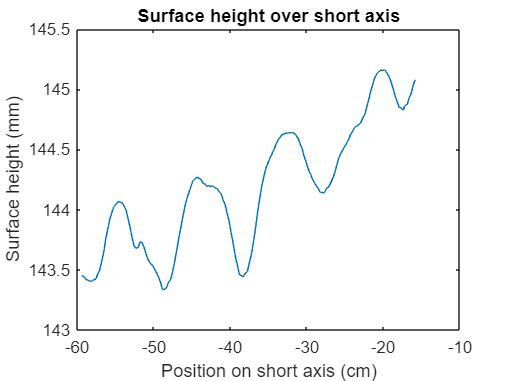

clear 
close all
clc


% To fill in right parameters and convert data files to surface height

ampl_value = 7;
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\20240909_full_plate_final\\20240909_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\',rot_rate,freq_value,string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\20240909_full_plate_final_results\\20240909_%sradps_%sHz_%smm_full_plate\\FFT\\',rot_rate,freq_value,string(ampl_value));

% input_dir = 'D:\Matlab\Matlab input\20240715_full_plate\20240715_rot_2.6Hz_9mm_full_plate_separate_frames\Results\';
% output_dir = 'D:\Matlab\Matlab output\20240715_full_plate_results\20240715_rot_2.6Hz_9mm_full_plate\FFT\';


% Define the base file name and extension
base_file_name = sprintf('20240909_%sradps_%sHz_%smm_full_plate_frame_',rot_rate,freq_value,string(ampl_value));

% base_file_name = '20240715_rot_2.6Hz_9mm_full_plate_frame_';


file_extension = 'A_vel_new.dat';

frame_num = 170;
% Construct the file name
frame_str = sprintf('%04d', frame_num);
file_name = [base_file_name, frame_str, file_extension];
input_file = fullfile(input_dir, file_name);

% Load the data
dr = loadvec(input_file);

% Copy dr to dr_new & delete rows and columns with only zeros
dr_new = dr;
dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

% Compute the surface height
h_0 = 150; % surface-pattern distance in mm
h = surfheight(dr_new, h_0);
surface_height = h.w;


% Surface height on short axis
% Plot the amplitude/surface height over the short axis
surf_height_short_axis = surface_height(170,:);
ampl_short_axis = surf_height_short_axis;
values_short_axis = h.y/10; % in cm
plot(values_short_axis,surf_height_short_axis)
title('Surface height over short axis')
xlabel('Position on short axis (cm)')
ylabel('Surface height (mm)')

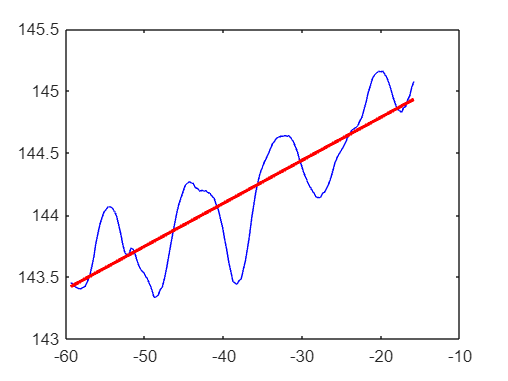


p = polyfit(values_short_axis, ampl_short_axis, 1);  % Degree 1 for a linear trend
trendline = polyval(p, values_short_axis);           % Compute the trendline
plot(values_short_axis, ampl_short_axis, 'b');       % Plot original data
hold on;
plot(values_short_axis, trendline, 'r', 'LineWidth', 2);  % Plot the trendline
hold off;

slope = p(1)

slope = 0.0347



% output_file_png_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_surf_height_short);
% output_file_fig_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_surf_height_short);

